# RSC, Breadth-first search

The following code uses the PRM method to generate random points in the free part of the map, and then join the points to generate the graph.

Then the path from the starting point to the end point is obtained using the BFS algorithm. 

Finally the path is made smoother.

clear all; close all; clc;

% Load map from a. mat file
data = load('map_straight_with_roundabout.mat');
% data = load('test/Files_mat/maps_5_1.mat');  % Sostituisci 'nome_file_mappa.mat' con il tuo percorso e nome del file

% Check available fields in 'data' structure
disp(fieldnames(data));

    {'map_straight_with_roundabout'}




% Extract map from data structure
map = data.map_straight_with_roundabout;
% map = data.invertedImage;

Start and goal point coordinates for the maps_5_1

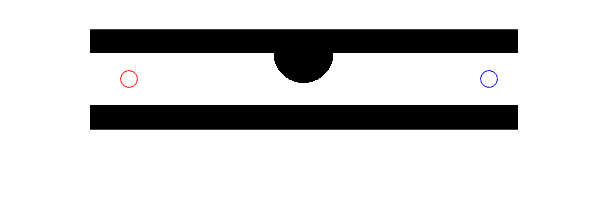

% %% maps_5_1
% x_start = 30;
% y_start = 80;
% x_goal = 269;           %215
% y_goal = 128;           %185

%% map_straight_with_roundabout
x_start = 40;
y_start = 50;
x_goal = 400;
y_goal = 0;

% Definition of start and goal points
Qs = [x_start, y_start];
Qg = [x_goal, y_goal];

% Plot initialization
figure;
imshow(map);
hold on;

% Plotting the start and goal points on the map
plot(x_start, y_start, 'ro', 'MarkerSize', 10);         % Start point (red)
plot(x_goal, y_goal, 'bo', 'MarkerSize', 10);           % Goal point (blue)

Parameters for PRM algorithm

numNodes = 400;         % Number of sample points
minDist = 15;           % Minimum distance between sample points
maxDist = 50;           % Maximum distance between sample points
resolution = 5;

Generate random sample points on the map

samplePoints = generateRandomPoints(numNodes, map, minDist, Qs, Qg);

Construct the PRM graph

adjacency_matrix = buildPRMGraph(samplePoints, map, minDist, maxDist, Qs, Qg);

Find the path using BFS

[parent, current] = findPathBFS(adjacency_matrix, samplePoints, Qs, Qg);

Reconstructs the previously obtained path plotting it

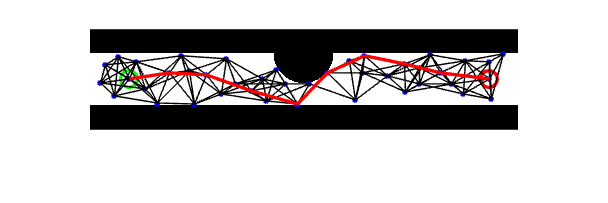

optimal_path = reconstructPath(parent, current, samplePoints);

From the smooth path it calculates the coordinates to be given input to the controller

pathController(smoothPath);

## FUNCTIONS

Generate random sample points on the map

function points = generateRandomPoints(numPoints, map, minDist, Qs, Qg)

    % Find all navigable (free) points in the map
    [navigableY, navigableX] = find(map == 1);
    navigablePoints = [navigableX, navigableY];
    totalNavigable = size(navigablePoints, 1);
    
    % Ensure we have enough navigable points
    if totalNavigable < numPoints
        error('Not enough navigable points to select from');
    end
    
    % Randomly select numPoints from navigable points
    selectedIndices = randperm(totalNavigable, numPoints);
    points = navigablePoints(selectedIndices, :);
    
    % Add start and end points to the list
    points = [Qs; Qg; points];
    
    % Filter points to ensure minimum distance constraint
    valid_points = [];
    for i = 1:numPoints
        if isempty(valid_points)
            valid_points = points(i, :);
        else
            % Check distances from the current point to all valid points
            distances = sqrt(sum((valid_points - points(i, :)).^2, 2));
            if all(distances >= minDist)
                valid_points = [valid_points; points(i, :)];
            end
        end
    end

    % Remove the initial generated points that don't meet the criteria, keeping start and end
    % valid_points = valid_points(3:end, :);

    points = valid_points;
    
end

Construct the PRM graph

function adjacency_matrix = buildPRMGraph(samplePoints, map, minDist, maxDist, Qs, Qg)

    numPoints = size(samplePoints, 1);
    % % Initialization of the nodes (samples) and adjacency matrix
    adjacency_matrix = zeros(numPoints, numPoints);
    % plot the generated points in blue
    figure;
    imshow(map); hold on;
    plot(Qs(1), Qs(2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
    plot(Qg(1), Qg(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
    plot(samplePoints(:, 1), samplePoints(:, 2), 'b.', 'MarkerSize', 10);  % Plot the generated points in blu
    
    % Building the roadmap (PRM)
    for i = 3:numPoints
        for j = i+1:numPoints
            % Check if points i and j are within max_dist
            distance = norm(samplePoints(i,:) - samplePoints(j,:));
            if (distance <= maxDist && distance >= minDist)
                % Check if the path between points i and j is obstacle-free
                line_points = round([linspace(samplePoints(i,1), samplePoints(j,1), 300); linspace(samplePoints(i,2), samplePoints(j,2), 300)]');
                valid_points = all(line_points >= 1, 2) & line_points(:,1) <= size(map,2) & line_points(:,2) <= size(map,1);
                if all(map(sub2ind(size(map), line_points(valid_points,2), line_points(valid_points,1))) == 1)
                    % If obstacle-free, connect i and j
                    adjacency_matrix(i,j) = 1;
                    adjacency_matrix(j,i) = 1;
                    % Plot the edge between points i and j
                    line([samplePoints(i,1), samplePoints(j,1)], [samplePoints(i,2), samplePoints(j,2)], 'Color', 'k');
                end
            end
        end
    end
    
    % Ensure start and end points are connected to the roadmap
    for k = [1, 2] % 1 for start, 2 for end
        for j = 3:numPoints % Iterate over all other points
            distance = norm(samplePoints(k,:) - samplePoints(j,:));
            if (distance <= maxDist)
                % Check if the path between points i and j is obstacle-free
                line_points = round([linspace(samplePoints(k,1), samplePoints(j,1), 300); linspace(samplePoints(k,2), samplePoints(j,2), 300)]');
                valid_points = all(line_points >= 1, 2) & line_points(:,1) <= size(map,2) & line_points(:,2) <= size(map,1);
                if all(map(sub2ind(size(map), line_points(valid_points,2), line_points(valid_points,1))) == 1)
                    % If obstacle-free, connect i and j
                    adjacency_matrix(k,j) = 1;
                    adjacency_matrix(j,k) = 1;
                    % Plot the edge between points i and j
                    line([samplePoints(k,1), samplePoints(j,1)], [samplePoints(k,2), samplePoints(j,2)], 'Color', 'k');
                end
            end
        end
    end
end

Find the path using BFS

% Function to find path using BFS
function [parent, current] = findPathBFS(adjacency_matrix, samplePoints, Qs, Qg)
    nodes = samplePoints;
    num_samples = size(nodes, 1);

    % Find indices of start and goal nodes in nodes array
    [~, q_start_index] = min(pdist2(nodes, Qs));
    [~, q_goal_index] = min(pdist2(nodes, Qg));

    % BFS initialization
    queue = q_start_index;              % Start with the index of the start node
    parent = zeros(1, num_samples);
    visited = false(1, num_samples);
    visited(q_start_index) = true;      % Mark start node as visited

    % BFS search
    while ~isempty(queue)
        current = queue(1);
        queue(1) = [];
        
        if current == q_goal_index
            % Reconstruct the path from goal to start
            % Interpolate the path using splines
            % Both are done in the main
            return;
        end
        
        % Explore neighbors (nodes connected to current)
        neighbors = find(adjacency_matrix(current,:) == 1);
        for i = 1:length(neighbors)
            if ~visited(neighbors(i))
                visited(neighbors(i)) = true;
                parent(neighbors(i)) = current;
                queue(end+1) = neighbors(i);
            end
        end
    end
end

Reconstructs the previously obtained path plotting it

function path = reconstructPath(parent, goal, nodes)
    path = [];
    current = goal;
    while current ~= 0
        path = [current, path];
        current = parent(current);
    end
    plotPath(path, nodes, 'r');
end

function plotPath(path, nodes, color)
    for i = 1:length(path)-1
        line( [nodes(path(i),1), nodes(path(i+1),1)], [nodes(path(i),2), nodes(path(i+1),2)], 'Color', color, 'LineWidth', 2);
    end
end

From the smooth path it calculates the coordinates to be given input to the controller

function pathController(smoothPath)

    x_d = smoothPath(:, 1);
    y_d = smoothPath(:, 2);

    % Calculation of speed (xd, yd) and orientation (thetad)
    dx_d = smoothPath(2:end, 1) - smoothPath(1:end-1, 1);           % Derived from x axis time
    dy_d = smoothPath(2:end, 2) - smoothPath(1:end-1, 2);           % Derived from y axis time
    ddx_d = diff(dx_d(1:end-1));                                    % Resize the array to match
    ddy_d = diff(dy_d(1:end-1));                                    % Resize the array to match
    theta_d = atan2(dy_d, dx_d);                                    % Orientation (angle to x axis)
    l = 0.5;
    phi_d = atan(l*(ddy_d.*dx_d(1:end-2) - ddx_d.*dy_d(1:end-2)));  % Derivative of the orientation with respect to time
    time = linspace(0, length(x_d)-1, length(x_d));                 % Create a time vector
    time1 = linspace(0, length(theta_d)-1, length(theta_d));        % Create a time vector
    time2 = linspace(0, length(phi_d)-1, length(phi_d));            % Create a time vector
    xd = timeseries(x_d, time);
    yd = timeseries(y_d, time);
    thetad = timeseries(theta_d, time1);
    phid = timeseries(phi_d, time2);

    % Trajectory plot in terms of xd, yd, thetad (for verification)
    figure;
    plot(x_d, 'r', 'LineWidth', 2); hold on;
    plot(y_d, 'b', 'LineWidth', 2);
    plot(theta_d, 'g', 'LineWidth', 2);
    plot(phi_d, 'k', 'LineWidth', 2);
    legend('xd', 'yd', 'thetad', 'phid');
    xlabel('Time');
    ylabel('Values');
    title('Trajectory in terms of xd, yd, thetad, phid');
end